load('TTC data files/B1965run2.mat')

Inflation pressure of 12 psi goes from 1-19984

12 psi, 0 camber is 1-7495

1-1249

1250-2498

2499-3746

3747-4996

4997-6245

6246-7495

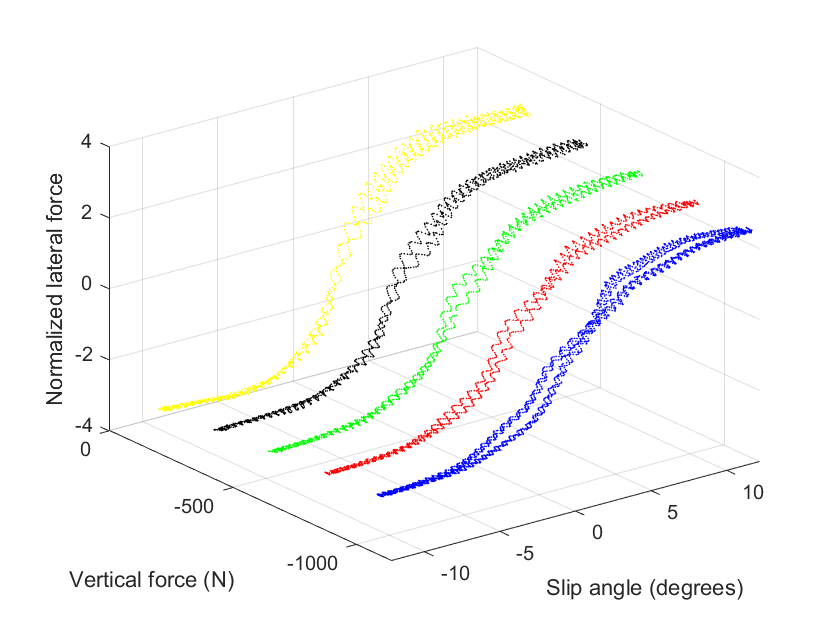

length=size(ET);
scatter3(SA(1:1249),FZ(1:1249),NFY(1:1249),1,'blue','filled')
hold on
scatter3(SA(1250:2498),FZ(1250:2498),NFY(1250:2498),1,'red','filled')
scatter3(SA(2499:3746),FZ(2499:3746),NFY(2499:3746),1,'green','filled')
scatter3(SA(3747:4996),FZ(3747:4996),NFY(3747:4996),1,'yellow','filled')
scatter3(SA(4997:6245),FZ(4997:6245),NFY(4997:6245),1,'blue','filled')
scatter3(SA(6246:7495),FZ(6246:7495),NFY(6246:7495),1,'black','filled')
xlabel('Slip angle (degrees)')
ylabel('Vertical force (N)')
zlabel('Normalized lateral force')
hold off

Plot one band:

scatter(SA(312:936),NFY(312:936),5,'filled')

Fit Pacejka function to data:

C0=[1 1 1 1]

C0 =      1     1     1     1


[C,resnorm,~,exitflag,output] = lsqcurvefit(@(C,x) pacejka(C,x),C0,SA(312:936),NFY(312:936))


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.000000e+02.



C =     0.3367    0.1740   10.8932    0.0944


resnorm = 2.5240

exitflag = 0

output = struct with fields:
    firstorderopt: 2.1835
       iterations: 80
        funcCount: 405
     cgiterations: 0
        algorithm: 'trust-region-reflective'
         stepsize: 0.0781
          message: '↵Solver stopped prematurely.↵↵lsqcurvefit stopped because it exceeded the function evaluation limit,↵options.MaxFunctionEvaluations = 4.000000e+02.↵↵'


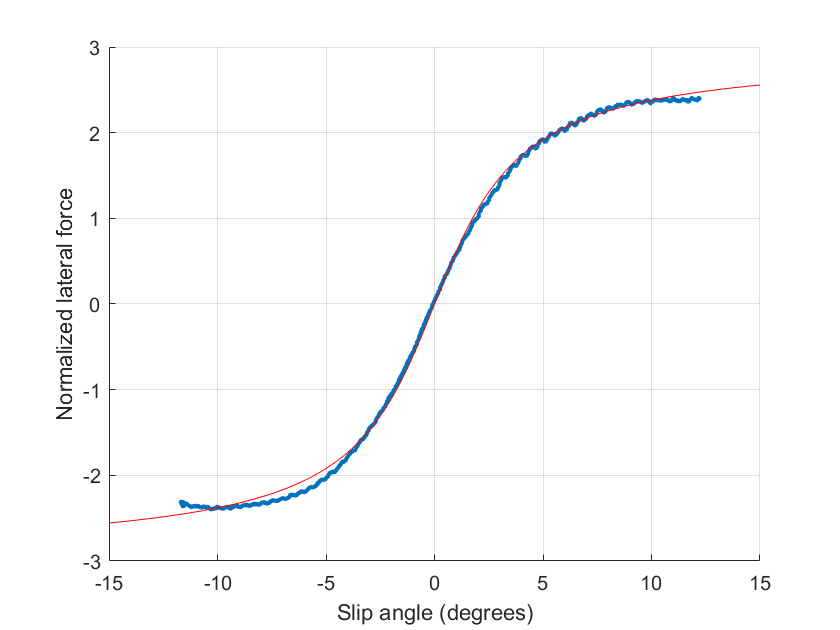

x=linspace(-15,15);
hold on
plot(x,pacejka(C,x),'red')
xlabel('Slip angle (degrees)')
ylabel('Normalized lateral force')
grid on

Define Pacejka function:

function y = pacejka(C,x)
y=C(3)*sin(C(2)*atan(C(1)*(1-C(4))*x+C(4)*atan(C(1)*x)));
end